# Timing Symv_unb_var[1-8]

This live script helps you visualize the performance of symmetric matrix-vector multiplication algorithms implemented with FLAMEC

## Load the timing data

clear
output

## Check if the answers for the different implementations are correct

max_diff = max( abs( data_unb_var2(:,3) ) )

max_diff = 1.8474e-13

if ( max_diff > 1.0e-12 )
    disp( 'Trouble in paradise?' );
else
    disp( 'All seems to be well' );
end

All seems to be well



max_diff = max( abs( data_unb_var4( :, 3 ) ) )

max_diff = 4.8317e-13

if ( max_diff > 1.0e-12 )
    disp( 'Trouble in paradise' );
else
    disp( 'All seems to be well' );
end

All seems to be well


## Plot

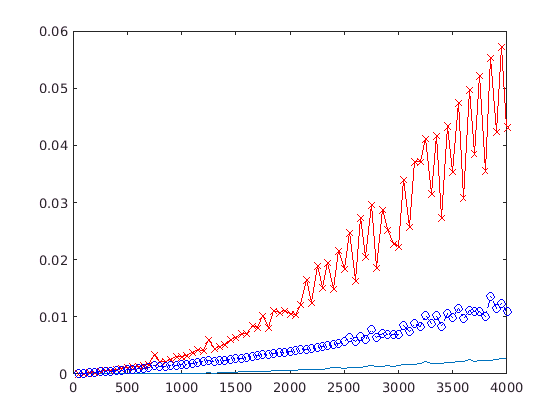

plot( data_ref( :, 1 ), data_ref( :, 2 ), '-' )
hold on
plot( data_unb_var2(:,1), data_unb_var2(:,2), 'x-r' );
plot( data_unb_var4(:,1), data_unb_var4(:,2), 'o-.b' );